# Voice Activity Detection in Noise Using Deep Learning

This example shows how to detect regions of speech in a low signal-to-noise environment using deep learning. The example uses the Speech Commands Dataset to train a Bidirectional Long Short-Term Memory (BiLSTM) network to detect voice activity.

Note: for the following exercise, please turn the speakers on.

Some of the functions used in this livescript require the Signal Processing Toolbox™ or the Matlab Audio Toolbox™. If these support packages are not installed, the functions provide the download links.

% Clear workspace and command window
clear;
clc;

## Introduction

Voice activity detection (VAD) is an essential component of many audio systems, such as automatic speech recognition and speaker recognition. Voice activity detection can be especially challenging in low signal-to-noise (SNR) situations, where speech is obstructed by noise.

This example uses long short-term memory ([LSTM](https://www.mathworks.com/help/deeplearning/ug/long-short-term-memory-networks.html)) networks, which are a type of recurrent neural network (RNN) well-suited to study sequence and time-series data. An LSTM network can learn long-term dependencies between time steps of a sequence. An LSTM layer ([lstmLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html)) can look at the time sequence in the forward direction, while a bidirectional LSTM layer ([bilstmLayer](https://www.mathworks.com/help/nnet/ref/nnet.cnn.layer.bilstmlayer.html)) can look at the time sequence in both forward and backward directions. This example uses a bidirectional LSTM layer.

This example trains a voice activity detection bidirectional LSTM network with feature sequences of spectral characteristics and a harmonic ratio metric.

### Access and process the data

In high SNR scenarios, traditional speech detection algorithms perform adequately. Read in an audio file that consists of words spoken with pauses between. Resample the audio to 16 kHz and normalize it to let the peak of the speech have a known value. Listen to the audio.

fs = 16e3;  % Sampling frequence
[speech,fileFs] = audioread('Counting-16-44p1-mono-15secs.wav');
speech = resample(speech,fs,fileFs); % Resempling the audio to 16kHz 
speech = speech/max(abs(speech));   %normalize the signal
sound(speech,fs)                    %Listen the audio 

### Detect Speech

The [`detectSpeech`](https://it.mathworks.com/help/audio/ref/detectspeech.html) function is a Matlab function that detects boundaries of speech in audio signal using the algorithm in [1]. The algorithm uses a thresholding algorithm based on energy and spectral spread per analysis frame. 

Use the [`detectSpeech`](https://it.mathworks.com/help/audio/ref/detectspeech.html) function to locate regions of speech. The `detectSpeech` function correctly identifies all regions of speech.

Specifing the "window" parameter of the `detectSpeech` function, we limit and weight the search with a window function in time domain. The [`hamming`](https://www.mathworks.com/help/signal/ref/hamming.html) function is used in this case. 

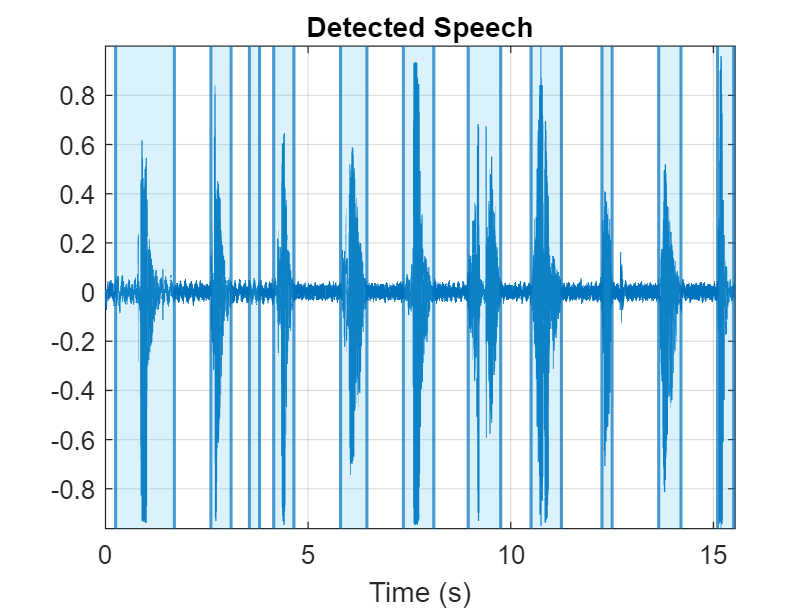

win = hamming(50e-3 * fs,'periodic');
detectSpeech(speech,fs,'Window',win)

### Add noise and detect speech

Corrupt the audio signal with washing machine noise at a -20 dB SNR. Listen to the corrupted audio and then call `detectSpeech` on the noisy audio signal.

[noise,fileFs] = audioread('WashingMachine-16-8-mono-200secs.mp3'); % Noise audio
noise = resample(noise,fs,fileFs);  % Resempling the audio to 16kHz 

SNR = -20; % Noise level
noiseGain = 10^(-SNR/20) * norm(speech) / norm(noise);

noisySpeech = speech + noiseGain*noise(1:numel(speech));
noisySpeech = noisySpeech./max(abs(noisySpeech));

sound(noisySpeech,fs)

detectSpeech(noisySpeech,fs,'Window',win)

As you can see, the function fails to detect the speech regions given the very low SNR.

## Train the Voice Activation Detection (VAD) Network

In this section we will train a Bidirectional Long Short-Term Memory (BiLSTM) network to detect voice activity. Since the time required to download the dataset and training the network is high, you can choose to skip this section and go directly to Test VAD Network section (select `doTraining=false` to load the pretrained network). 

### Introduction

Workflow steps:

- Create an [audioDatastore](docid:audio_ref#mw_6315b106-9a7b-4a11-a7c6-322c073e343a) that points to the audio speech files used to train the LSTM network.

- Create a training signal consisting of speech segments separated by segments of silence of varying durations.

- Corrupt the speech-plus-silence signal with washing machine noise (SNR = -10 dB).

- Extract feature sequences consisting of spectral characteristics and harmonic ratio from the noisy signal.

- Train the LSTM network using the feature sequences to identify regions of voice activity.

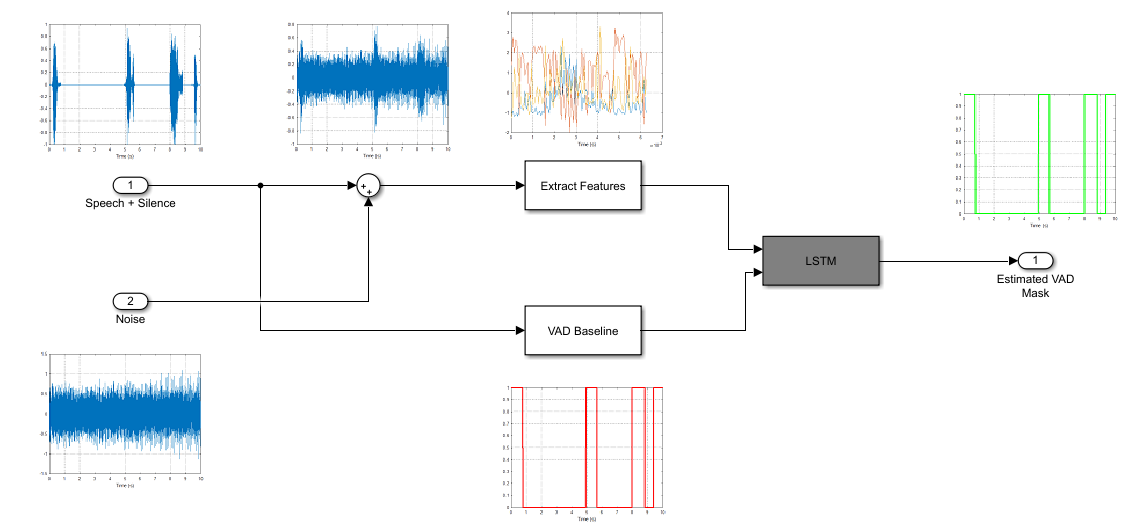

### Download the speech command data set

Download and extract the Google Speech Commands Dataset [2]. It may take a couple of minutes.

url = 'https://ssd.mathworks.com/supportfiles/audio/google_speech.zip';

downloadFolder = './';
datasetFolder = fullfile(downloadFolder,'google_speech');

if ~exist(datasetFolder,'dir')
    disp('Downloading Google speech commands data set (1.9 GB)...')
    unzip(url,downloadFolder)
end

Create an[ audioDatastore ](https://www.mathworks.com/help/audio/ref/audiodatastore.html)that points to the training data set and validation data set.

adsTrain = audioDatastore(fullfile(datasetFolder, 'train'), "Includesubfolders",true);
adsValidation = audioDatastore(fullfile(datasetFolder, 'validation'), "Includesubfolders",true);

### Create Speech-Plus-Silence Training Signal

Read the contents of an audio file using the Object function `read (see `[audioDatastore](https://www.mathworks.com/help/audio/ref/audiodatastore.html)). Get the sample rate from the `adsInfo` struct and listen the audio signal. 

[data,adsInfo] = read(adsTrain);
Fs = adsInfo.SampleRate;    % Sample rate of the dataset

Listen and plot the audio signal.

sound(data,Fs)

timeVector = (1/Fs) * (0:numel(data)-1);
plot(timeVector,data)
ylabel("Amplitude")
xlabel("Time (s)")
title("Sample Audio")
grid on

The signal has non-speech portions (silence, background noise, etc) that do not contain useful speech information. This example removes silence using the [`detectSpeech`](https://it.mathworks.com/help/audio/ref/detectspeech.html) function we have seen in the introduction.

Extract the useful portion of data. Define a 50 ms periodic Hamming window for analysis. Call `detectSpeech` to return the indices of the detected speech. Isolate the detected speech regions and then use the `sound` command to listen to the audio. Use `plotDetectedSpeech` to plot the results.

win = hamming(50e-3 * Fs,'periodic');

speechIndices = detectSpeech(data,Fs,'Window',win);

plotDetectedSpeech(data,Fs,speechIndices);

sound(data(speechIndices(1,1):speechIndices(1,2)),Fs)

The `detectSpeech` function returns indices that tightly surround the detected speech region. It was determined empirically that, for this example, extending the indices of the detected speech by five frames on either side increased the final model's performance. Extend the speech indices by five frames and then listen to the speech. 

speechIndices(1,1) = max(speechIndices(1,1) - 5*numel(win),1);
speechIndices(1,2) = min(speechIndices(1,2) + 5*numel(win),numel(data));

sound(data(speechIndices(1,1):speechIndices(1,2)),Fs);

plotDetectedSpeech(data,Fs,speechIndices);

Reset the training datastore and shuffle the order of files in the datastores.

reset(adsTrain)
adsTrain = shuffle(adsTrain);
adsValidation = shuffle(adsValidation);

The `detectSpeech` function calculates statistics-based thresholds to determine the speech regions. You can skip the threshold calculation and speed up the `detectSpeech` function by specifying the thresholds directly. To determine thresholds for a data set, call `detectSpeech` on a sampling of files and get the thresholds it calculates. Take the mean of the thresholds. 

TM = [];
for index1 = 1:500
     data = read(adsTrain); 
     [~,T] = detectSpeech(data,Fs,'Window',win);
     TM = [TM;T];
end

T = mean(TM);

reset(adsTrain)

Create a 1000-second training signal by combining multiple speech files from the training data set. Use `detectSpeech` to remove unwanted portions of each file. Insert a random period of silence between speech segments.

% Preallocate the training signal.
duration = 2000*Fs;
audioTraining = zeros(duration,1);

% Preallocate the voice activity training mask. 
% Values of 1 in the mask correspond to samples located in areas with voice activity. 
% Values of 0 correspond to areas with no voice activity.
maskTraining = zeros(duration,1); 

%Specify a maximum silence segment duration of 2 seconds.
maxSilenceSegment = 2; 

% Construct the training signal by calling read on the datastore in a loop.
numSamples = 1;    

while numSamples < duration
    data = read(adsTrain);
    data = data ./ max(abs(data)); % Normalize amplitude

    % Determine regions of speech
    idx = detectSpeech(data,Fs,'Window',win,'Thresholds',T);

    % If a region of speech is detected
    if ~isempty(idx)
        
        % Extend the indices by five frames
        idx(1,1) = max(1,idx(1,1) - 5*numel(win));
        idx(1,2) = min(length(data),idx(1,2) + 5*numel(win));
        
        % Isolate the speech
        data = data(idx(1,1):idx(1,2));
        
        % Write speech segment to training signal
        audioTraining(numSamples:numSamples+numel(data)-1) = data;
        
        % Set VAD baseline
        maskTraining(numSamples:numSamples+numel(data)-1) = true;
        
        % Random silence period
        numSilenceSamples = randi(maxSilenceSegment*Fs,1,1);
        numSamples = numSamples + numel(data) + numSilenceSamples;
    end
end

Visualize and listen a 10-second portion of the training signal. Plot the baseline voice activity mask.

figure
range = 1:10*Fs;
plot((1/Fs)*(range-1),audioTraining(range));
hold on
plot((1/Fs)*(range-1),maskTraining(range));
grid on
lines = findall(gcf,"Type","Line");
lines(1).LineWidth = 2;
xlabel("Time (s)")
legend("Signal","Speech Region")
title("Training Signal (first 10 seconds)");

% Listen to the first 10 seconds of the training signal.
sound(audioTraining(range),Fs);

### Add Noise to the Training Signal

Corrupt the training signal with washing machine noise by adding washing machine noise to the speech signal such that the signal-to-noise ratio is -10 dB.

% Read 8 kHz noise and convert it to 16 kHz.
noise = audioread("WashingMachine-16-8-mono-1000secs.mp3");
noise = resample(noise,2,1);

% Corrupt training signal with noise.
audioTraining = audioTraining(1:numel(noise));
SNR = -10;
noise = 10^(-SNR/20) * noise * norm(audioTraining) / norm(noise);
audioTrainingNoisy = audioTraining + noise; 
audioTrainingNoisy = audioTrainingNoisy / max(abs(audioTrainingNoisy));

% Visualize a 10-second portion of the noisy training signal. Plot the baseline voice activity mask.
figure
plot((1/Fs)*(range-1),audioTrainingNoisy(range));
hold on
plot((1/Fs)*(range-1),maskTraining(range));
grid on
lines = findall(gcf,"Type","Line");
lines(1).LineWidth = 2;
xlabel("Time (s)")
legend("Noisy Signal","Speech Area")
title("Training Signal (first 10 seconds)");

% Listen to the first 10 seconds of the noisy training signal.
sound(audioTrainingNoisy(range),Fs)

Note that you obtained the baseline voice activity mask using the noiseless speech-plus-silence signal. Verify that using `detectSpeech` on the noise-corrupted signal does not yield good results.

speechIndices = detectSpeech(audioTrainingNoisy,Fs,'Window',win);

speechIndices(:,1) = max(1,speechIndices(:,1) - 5*numel(win));
speechIndices(:,2) = min(numel(audioTrainingNoisy),speechIndices(:,2) + 5*numel(win));

noisyMask = zeros(size(audioTrainingNoisy));
for ii = 1:size(speechIndices)
    noisyMask(speechIndices(ii,1):speechIndices(ii,2)) = 1;
end

% Visualize a 10-second portion of the noisy training signal. 
% Plot the voice activity mask obtained by analyzing the noisy signal.
figure
plot((1/Fs)*(range-1),audioTrainingNoisy(range));
hold on
plot((1/Fs)*(range-1),noisyMask(range));
grid on
lines = findall(gcf,"Type","Line");
lines(1).LineWidth = 2;
xlabel("Time (s)")
legend("Noisy Signal","Mask from Noisy Signal")
title("Training Signal (first 10 seconds)");

### Create Speech-Plus-Silence Validation Signal

Create a 200-second noisy speech signal to validate the trained network. Use the validation datastore. Note that the validation and training datastores have different speakers.

% Preallocate the validation signal and the validation mask.
% You will use this mask to assess the accuracy of the trained network.
duration = 200*Fs;
audioValidation = zeros(duration,1);
maskValidation = zeros(duration,1);

% Construct the validation signal by calling read on the datastore in a loop.
numSamples = 1;    
while numSamples < duration
    data = read(adsValidation);
    data = data ./ max(abs(data)); % Normalize amplitude
    
    % Determine regions of speech
    idx = detectSpeech(data,Fs,'Window',win,'Thresholds',T);
    
    % If a region of speech is detected
    if ~isempty(idx)
        
        % Extend the indices by five frames
        idx(1,1) = max(1,idx(1,1) - 5*numel(win));
        idx(1,2) = min(length(data),idx(1,2) + 5*numel(win));

        % Isolate the speech
        data = data(idx(1,1):idx(1,2));
        
        % Write speech segment to validation signal
        audioValidation(numSamples:numSamples+numel(data)-1) = data;
        
        % Set VAD Baseline
        maskValidation(numSamples:numSamples+numel(data)-1) = true;
        
        % Random silence period
        numSilenceSamples = randi(maxSilenceSegment*Fs,1,1);
        numSamples = numSamples + numel(data) + numSilenceSamples;
    end
end

Corrupt the validation signal with washing machine noise by adding washing machine noise to the speech signal such that the signal-to-noise ratio is -10 dB. Use a different noise file for the validation signal than you did for the training signal.

noise = audioread("WashingMachine-16-8-mono-200secs.mp3");
noise = resample(noise,2,1);
noise = noise(1:duration);
audioValidation = audioValidation(1:numel(noise));

noise = 10^(-SNR/20) * noise * norm(audioValidation) / norm(noise);
audioValidationNoisy = audioValidation + noise; 
audioValidationNoisy = audioValidationNoisy / max(abs(audioValidationNoisy));

### Extract Training Features

This example trains the LSTM network using the following features:

- [`spectralCentroid`](https://it.mathworks.com/help/audio/ref/spectralcentroid.html)

- [`spectralCrest`](https://it.mathworks.com/help/audio/ref/spectralcrest.html)

- [`spectralEntropy`](https://it.mathworks.com/help/audio/ref/spectralentropy.html)

- [`spectralFlux`](https://it.mathworks.com/help/audio/ref/spectralflux.html)

- [`spectralKurtosis`](https://it.mathworks.com/help/audio/ref/spectralkurtosis.html)

- [`spectralRolloffPoint`](https://it.mathworks.com/help/audio/ref/spectralrolloffpoint.html)

- [`spectralSkewness`](https://it.mathworks.com/help/audio/ref/spectralskewness.html)

- [`spectralSlope`](https://it.mathworks.com/help/audio/ref/spectralslope.html)

- [`harmonicRatio`](https://it.mathworks.com/help/audio/ref/harmonicratio.html)

This example uses [audioFeatureExtractor](https://it.mathworks.com/help/audio/ref/audiofeatureextractor.html) to create an optimal feature extraction pipeline for the feature set. Create an `audioFeatureExtractor` object to extract the feature set. Use a 256-point Hann window with 50% overlap. See the documentation for a complete list of features that could be extracted with the  `audioFeatureExtractor` object. 

afe = audioFeatureExtractor('SampleRate',Fs, ...
    'Window',hann(256,"Periodic"), ...
    'OverlapLength',128, ...
    ...
    'spectralCentroid',true, ...    % Selected features
    'spectralCrest',true, ...
    'spectralEntropy',true, ...
    'spectralFlux',true, ...
    'spectralKurtosis',true, ...
    'spectralRolloffPoint',true, ...
    'spectralSkewness',true, ...
    'spectralSlope',true, ...
    'harmonicRatio',true);

featuresTraining = extract(afe,audioTrainingNoisy);

Display the dimensions of the features matrix. The first dimension corresponds to the number of windows the signal was broken into (it depends on the window length and the overlap length). The second dimension is the number of features used in this example.

[numWindows,numFeatures] = size(featuresTraining)

In classification applications, it is a good practice to normalize all features to have zero mean and unity standard deviation.

Compute the mean and standard deviation for each coefficient, and use them to normalize the data.

M = mean(featuresTraining,1);
S = std(featuresTraining,[],1);
featuresTraining = (featuresTraining - M) ./ S;

Extract the features from the validation signal using the same process.

featuresValidation = extract(afe,audioValidationNoisy);
featuresValidation = (featuresValidation - mean(featuresValidation,1)) ./ std(featuresValidation,[],1);

Each feature corresponds to 128 samples of data (the hop length). For each hop, set the expected voice/no voice value to the mode of the baseline mask values corresponding to those 128 samples. Convert the voice/no voice mask to categorical.

windowLength = numel(afe.Window);
hopLength = windowLength - afe.OverlapLength;
range = (hopLength) * (1:size(featuresTraining,1)) + hopLength;
maskMode = zeros(size(range));
for index = 1:numel(range)
    maskMode(index) = mode(maskTraining( (index-1)*hopLength+1:(index-1)*hopLength+windowLength ));
end
maskTraining = maskMode.';

maskTrainingCat = categorical(maskTraining);

Do the same for the validation mask.

range = (hopLength) * (1:size(featuresValidation,1)) + hopLength;
maskMode = zeros(size(range));
for index = 1:numel(range)
    maskMode(index) = mode(maskValidation( (index-1)*hopLength+1:(index-1)*hopLength+windowLength ));
end
maskValidation = maskMode.';

maskValidationCat = categorical(maskValidation);

Split the training features and the mask into sequences of length 800, with 75% overlap between consecutive sequences.

sequenceLength = 800;
sequenceOverlap = round(0.75*sequenceLength);

trainFeatureCell = helperFeatureVector2Sequence(featuresTraining',sequenceLength,sequenceOverlap);
trainLabelCell = helperFeatureVector2Sequence(maskTrainingCat',sequenceLength,sequenceOverlap);

### Define the LSTM Network Architecture

Specify the input size of the [sequenceInputLayer](https://it.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.sequenceinputlayer.html) to be sequences of length 9 (the number of features). Specify two hidden bidirectional LSTM layers with the same parameters: output size of 200 and output a sequence. This command instructs the bidirectional LSTM layer to map the input time series into 200 features that are passed to the next layer and the fully connected layer. Finally, specify two classes by including a fully connected layer of size 2, followed by a softmax layer and a classification layer.

layers = [ ...    
    sequenceInputLayer( size(featuresValidation,2) )    
    bilstmLayer(200,"OutputMode","sequence")   
    bilstmLayer(200,"OutputMode","sequence")   
    fullyConnectedLayer(2)   
    softmaxLayer   
    classificationLayer      
    ];

Next, specify the training options for the classifier. 

This example uses the adaptive moment estimation (ADAM) solver. ADAM performs better with recurrent neural networks (RNNs) like LSTMs than the default stochastic gradient descent with momentum (SGDM) solver.

maxEpochs = 20;
miniBatchSize = 64;
options = trainingOptions("adam", ...
    "MaxEpochs",maxEpochs, ...
    "MiniBatchSize",miniBatchSize, ...
    "Shuffle","every-epoch", ...
    "Verbose",0, ...
    "SequenceLength",sequenceLength, ...
    "ValidationFrequency",floor(numel(trainFeatureCell)/miniBatchSize), ...
    "ValidationData",{featuresValidation.',maskValidationCat.'}, ...
    "Plots","training-progress", ...
    "LearnRateSchedule","piecewise", ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",5);

### Train the LSTM Network

Train the LSTM network with the specified training options and layer architecture using `trainNetwork`. Because the training set is large, the training process can take several minutes.

doTraining = false;
if doTraining
   [speechDetectNet,netInfo] = trainNetwork(trainFeatureCell,trainLabelCell,layers,options);
   fprintf("Validation accuracy: %f percent.\n", netInfo.FinalValidationAccuracy);
else
    load('Audio_VoiceActivityDetectionExample.mat','speechDetectNet','afe');
end

## Test VAD Network

After training the network we evaluate the performance of the network on the test dataset. Here is a sketch of the prediction process. You use the trained network to make predictions.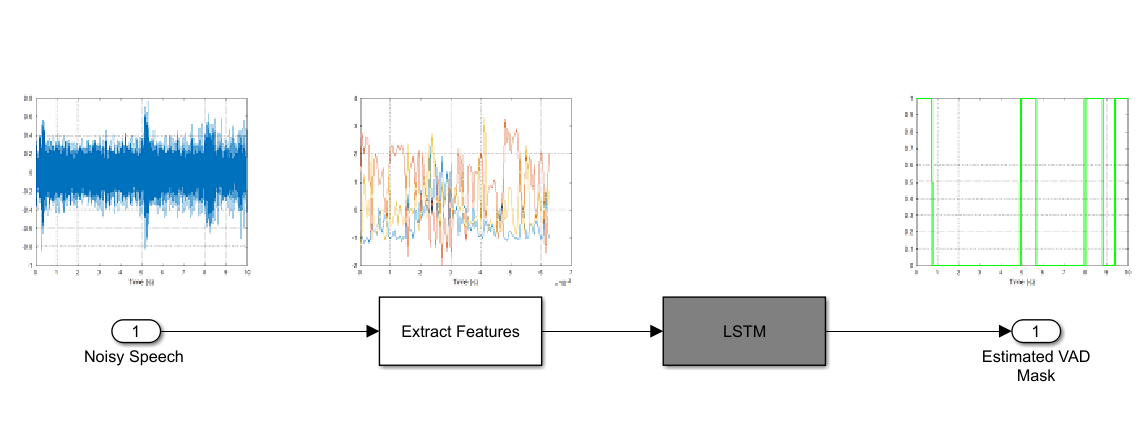

### Create Testing Dataset

Create an[ audioDatastore ](https://www.mathworks.com/help/audio/ref/audiodatastore.html)that points to the testing data set .

adsTest = audioDatastore(fullfile(datasetFolder, 'test'), "Includesubfolders",true);

Create a 500-second noisy speech signal to test the trained network using the test datastore. Note that the testing and training datastores have different speakers.

As done before we pre-allocate the testing signal and the testing mask. You will use this mask to assess the accuracy of the trained network.

duration = 200*Fs;
audioTest = zeros(duration,1);
maskTest = zeros(duration,1);

numSamples = 1;    
while numSamples < duration
    data = read(adsTest);
    data = data ./ max(abs(data)); % Normalize amplitude
    
    % Determine regions of speech
    idx = detectSpeech(data,Fs,'Window',win,'Thresholds',T);
    
    % If a region of speech is detected
    if ~isempty(idx)
        
        % Extend the indices by five frames
        idx(1,1) = max(1,idx(1,1) - 5*numel(win));
        idx(1,2) = min(length(data),idx(1,2) + 5*numel(win));

        % Isolate the speech
        data = data(idx(1,1):idx(1,2));
        
        % Write speech segment to test signal
        audioTest(numSamples:numSamples+numel(data)-1) = data;
        
        % Set VAD Baseline
        maskTest(numSamples:numSamples+numel(data)-1) = true;
        
        % Random silence period
        numSilenceSamples = randi(maxSilenceSegment*Fs,1,1);
        numSamples = numSamples + numel(data) + numSilenceSamples;
    end
end

Corrupt the testing signal with washing machine noise by adding washing machine noise to the speech signal such that the signal-to-noise ratio is -10 dB. Use a different noise file for the testing signal than you did for the training signal.

noise = audioread("WashingMachine-16-8-mono-200secs.mp3");
noise = resample(noise,2,1);
noise = noise(1:duration);
audioTest = audioTest(1:numel(noise));

noise = 10^(-SNR/20) * noise * norm(audioTest) / norm(noise);
audioTestNoisy = audioTest + noise; 
audioTestNoisy = audioTestNoisy / max(abs(audioTestNoisy));

Extract the features from the testing signal using the same process we did for the training signals and set the correct voice/no voice mask.

featuresTest = extract(afe,audioTestNoisy);
featuresTest = (featuresTest - mean(featuresTest,1)) ./ std(featuresTest,[],1);

range = (hopLength) * (1:size(featuresTest,1)) + hopLength;
maskMode = zeros(size(range));
for index = 1:numel(range)
    maskMode(index) = mode(maskTest( (index-1)*hopLength+1:(index-1)*hopLength+windowLength ));
end
maskTest = maskMode.';

maskTestCat = categorical(maskTest);

### Test the network performace

Estimate voice activity in the validation signal using the trained network. Convert the estimated VAD mask from categorical to double.

EstimatedVADMask = classify(speechDetectNet,featuresTest.');
EstimatedVADMask = double(EstimatedVADMask);
EstimatedVADMask = EstimatedVADMask.' - 1;

Calculate and plot the validation confusion matrix from the vectors of actual and estimated labels.

figure
cm = confusionchart(maskValidation,EstimatedVADMask,"title","Validation Accuracy");
cm.ColumnSummary = "column-normalized";
cm.RowSummary = "row-normalized";

## Further Practice

- As you can see the test performance are low since the network parameters are not optimized and the network tend to overfitting. Try to change the parameters to improve the performance. 

## Further readings

[Audio Processing Using Deep Learning](https://it.mathworks.com/help/deeplearning/audio-processing-using-deep-learning.html)

[Extract Audio Features](https://it.mathworks.com/help/audio/ref/extractaudiofeatures.html) and [audioFeatureExtractor](https://it.mathworks.com/help/audio/ref/audiofeatureextractor.html)

## References

[1] Giannakopoulos, Theodoros. "A Method for Silence Removal and Segmentation of Speech Signals, Implemented in MATLAB", (University of Athens, Athens, 2009).

[2] Warden P. "Speech Commands: A public dataset for single-word speech recognition", 2017. Available from [https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz](https://storage.googleapis.com/download.tensorflow.org/data/speech_commands_v0.01.tar.gz). Copyright Google 2017. The Speech Commands Dataset is licensed under the Creative Commons Attribution 4.0 license

## Helper Functions

### Convert Feature Vectors to Sequences

function [sequences,sequencePerFile] = helperFeatureVector2Sequence(features,featureVectorsPerSequence,featureVectorOverlap)
    if featureVectorsPerSequence <= featureVectorOverlap
        error('The number of overlapping feature vectors must be less than the number of feature vectors per sequence.')
    end

    if ~iscell(features)
        features = {features};
    end
    hopLength = featureVectorsPerSequence - featureVectorOverlap;
    idx1 = 1;
    sequences = {};
    sequencePerFile = cell(numel(features),1);
    for ii = 1:numel(features)
        sequencePerFile{ii} = floor((size(features{ii},2) - featureVectorsPerSequence)/hopLength) + 1;
        idx2 = 1;
        for j = 1:sequencePerFile{ii}
            sequences{idx1,1} = features{ii}(:,idx2:idx2 + featureVectorsPerSequence - 1); %#ok<AGROW>
            idx1 = idx1 + 1;
            idx2 = idx2 + hopLength;
        end
    end
end

### Plot Detected Speech

function plotDetectedSpeech(audioIn,fs,speechIndices)

    t = (0:length(audioIn)-1)/fs;
    plot(t,audioIn)
    grid on
    hold on
    amax = max(audioIn);
    amin = min(audioIn);
    for idx = 1:size(speechIndices,1)
        xline(t(speechIndices(idx,1)),'color',[0 0.4470 0.7410],'LineWidth',1.2);
        patch([t(speechIndices(idx,1)),t(speechIndices(idx,1)),t(speechIndices(idx,2)),t(speechIndices(idx,2))], ...
            [amin,amax,amax,amin], ...
            [0.3010 0.7450 0.9330], ...
            'FaceAlpha',0.2,'EdgeColor','none');
        xline(t(speechIndices(idx,2)),'color',[0 0.4470 0.7410],'LineWidth',1.2);
    end
    xlabel(getString(message('audio:detectSpeech:TimeAxis')))
    if isempty(speechIndices)
        title(getString(message('audio:detectSpeech:PlotTitleNoSpeech')))
    else
        title(getString(message('audio:detectSpeech:PlotTitle')))
        
    end
    axis tight
    hold off
end